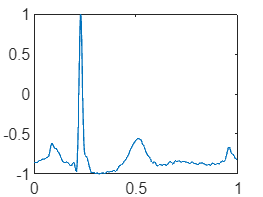

load('101m.mat');

% Define the sampling frequency
Fs = 360; % Hz

% Define the start and end indices for the 10-second segment
start_index = 1; % Start at the beginning of the signal
end_index = 360; % Extract 10 seconds of data

% Extract the 10-second segment from the ECG signal
ecg_data = val(1, start_index:end_index);

% Define the passband frequencies (in Hz)
low_freq = 0.5; % Lower cutoff frequency
high_freq =50; % Upper cutoff frequency

% Design the bandpass filter using 'butter' filter design
order = 4; % Filter order
[b, a] = butter(order, [low_freq high_freq] / (Fs/2), 'bandpass');

% Apply the bandpass filter to the ECG segment
ecg_filtered= filtfilt(b, a, ecg_data);


% Define the desired amplitude range for normalization (e.g., [-1, 1])
desired_min_amplitude = -1;
desired_max_amplitude = 1;

% Calculate the current minimum and maximum amplitudes in the filtered ECG signal
min_amplitude = min(ecg_filtered);
max_amplitude = max(ecg_filtered);

% Normalize the filtered ECG signal to the desired range
normalized_ecg = (ecg_filtered - min_amplitude) / (max_amplitude - min_amplitude) ...
               * (desired_max_amplitude - desired_min_amplitude) + desired_min_amplitude;
t_filtered = (0:length(normalized_ecg) - 1) / Fs;
figure;
plot(t_filtered,normalized_ecg)



% Initialize arrays to store Q and S point indices

% Define a search window for Q and S point detection
search_window =round(0.038*Fs) ; 
[peak_values,peak_indices]=max(normalized_ecg)

peak_values = 1

peak_indices = 83

% Iterate through R-peaks to find Q and S points
% Search for Q point (before R peak)
q_segment = -normalized_ecg(1 : peak_indices);
[q_peak_values,q_point_indices]=max(q_segment) 

q_peak_values = 0.9692

q_point_indices = 75

    
% Search for S point (after R peak)
s_segment = -normalized_ecg(peak_indices :end);
[s_peak_values,s_point_indices]=max(s_segment) 

s_peak_values = 1

s_point_indices = 35

    
% Search for P point (before Q peak)
p_segment = normalized_ecg(1 :q_point_indices );
[p_peak_values,p_point_indices]=max(p_segment) 

p_peak_values = -0.6178

p_point_indices = 33

% Search for T point (aftet S peak)
t_segment =normalized_ecg(s_point_indices+peak_indices:end);
[t_peak_values,t_point_indices]=max(t_segment) 

t_peak_values = -0.5564

t_point_indices = 67

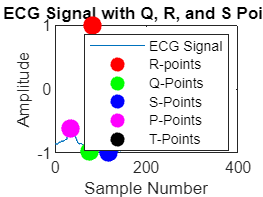

% Plot the original ECG signal with Q, R, and S points
t = (0:length(normalized_ecg) - 1);
figure;
plot(t, normalized_ecg);
hold on;
plot(peak_indices,normalized_ecg(peak_indices) , 'r.', 'MarkerSize',30);
plot(q_point_indices, normalized_ecg(q_point_indices), 'g.', 'MarkerSize', 30);
plot(s_point_indices+peak_indices, normalized_ecg(s_point_indices+peak_indices), 'b.', 'MarkerSize', 30);
plot(p_point_indices, normalized_ecg(p_point_indices), 'm.', 'MarkerSize', 30);
plot(t_point_indices+s_point_indices+peak_indices, normalized_ecg(t_point_indices+s_point_indices+peak_indices), 'k.', 'MarkerSize', 30);

title('ECG Signal with Q, R, and S Points');
xlabel('Sample Number');
ylabel('Amplitude');
legend('ECG Signal','R-points', 'Q-Points', 'S-Points','P-Points','T-Points');
hold off

%PR Interval
PR_interval=(peak_indices-p_point_indices)*1000/Fs

PR_interval = 138.8889


%ST Interval
ST_interval=(t_point_indices)*1000/Fs

ST_interval = 186.1111


%QRS Duration
QRS_Complex=(s_point_indices+peak_indices-q_point_indices)*1000/Fs

QRS_Complex = 119.4444


%QRS Amplitude
QRS_Amplitude=(ecg_filtered(peak_indices)-ecg_filtered(s_point_indices+peak_indices))/200

QRS_Amplitude = 1.4374